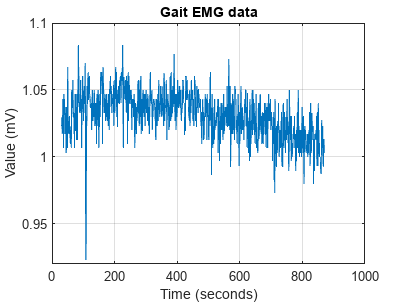

% Load the data from the "o1-76-si.txt" file
data = load('o1-76-si.txt');  % Adjust the filename as needed

% Extract time and stride interval data
time = data(:, 1);  % Assuming time is in the first column
stride_interval = data(:, 2);  % Assuming stride interval is in the second column

% Set the sampling frequency (adjust as needed)
fs = 1 / (time(2) - time(1));
% Perform Continuous Wavelet Transform
[cwt_coefficients, frequencies] = cwt(stride_interval, fs);

% Create a figure and plot the data
figure;
plot(time, stride_interval);
xlabel('Time (seconds)');
ylabel('Value (mV)');  % Fixed the ylabel text
title('Gait EMG data');
grid on;

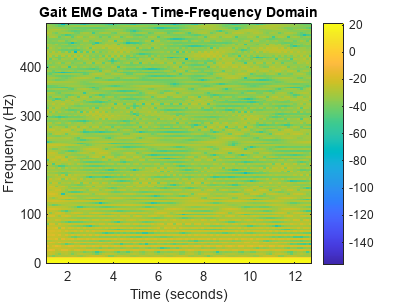



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Create a figure and plot the spectrogram

figure;
spectrogram(stride_interval, hamming(128), 120, 256, fs, 'yaxis'); % Adjusted parameters
title('Gait EMG Data - Time-Frequency Domain');
xlabel('Time (seconds)');
ylabel('Frequency (Hz)');
colorbar;  % Display color scale

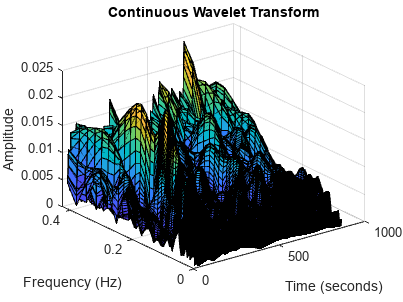




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Perform Continuous Wavelet Transform
[cwt_coefficients, frequencies] = cwt(stride_interval, fs);

% Create a time-frequency grid for 3D plotting
[time_grid, freq_grid] = meshgrid(time, frequencies);

% Plot each wavelet using a 3D surface plot
figure;
surf(time_grid, freq_grid, abs(cwt_coefficients));
xlabel('Time (seconds)');
ylabel('Frequency (Hz)');
zlabel('Amplitude');
title('Continuous Wavelet Transform');

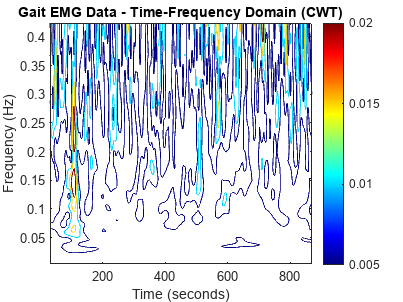





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create a figure and plot the CWT coefficients

figure;
contour(time, frequencies, abs(cwt_coefficients));
colormap('jet');
colorbar;
title('Gait EMG Data - Time-Frequency Domain (CWT)');
xlabel('Time (seconds)');
ylabel('Frequency (Hz)');

% Save the figure as a JPG image
saveas(gcf, 'cwt_plot.jpg');


% Load the saved image (remove the incorrect variable name)
cwt_plot_image = imread('cwt_plot.jpg');



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Extract classical features from the saved image
features = classicalfeatures(cwt_plot_image);

************ FEATURES EXTRACTION 1 ***************
Mean = 234.2489
Stdev = 54.5014
Range = 255
Median = 255
Interquartile Range = 3
ModeROI = 1
MeanBound = 234
Area = 572766
Perimeter = 2996.476
Compactness = 0.80161
MGR = 2.8766
VGR = 2.3994
RMS = 15.9198
IEMG = 134458874
SSI = 145473749
VAR = 2970.4022
Area of Power = 24891903131.4286
PKF = 0.0011429
Instantaneous RMS = 240.5056
Average RMS = 15.9198



% Display the extracted features
%disp('Classical Features:');
%disp(features);

size(cwt_coefficients)

ans =     68   815
